# `Image Thresholding `

Image thresholding can be performed for both greyscale and color images 

For greyscale Images, the threshold can be done in two ways,

- manual Thresholding - In this method, we will manually Identify the best possible thresholding value for image.

- Atomatic Thresholding - Use intensity base algorithms, to automatically identify best possible thresholding value for an image.

## Grayscale Manual Thresholding

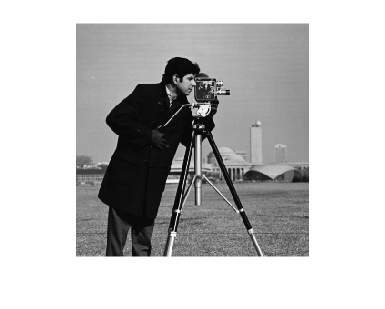

img=imread('cameraman.tif');
imshow(img);


%0 upto 255
th_val=75;

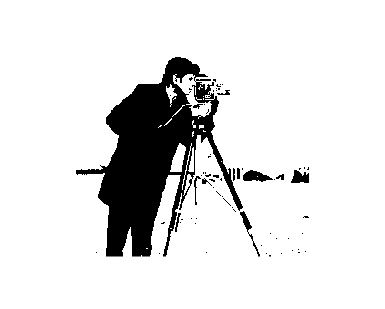

bin_im=imbinarize(img,th_val/255);
imshow(bin_im);

# `Greyscale Automatic Thresholding of Images: `

th_value_auto=graythresh(img);
th_int_auto=th_value_auto*255

th_int_auto = 88

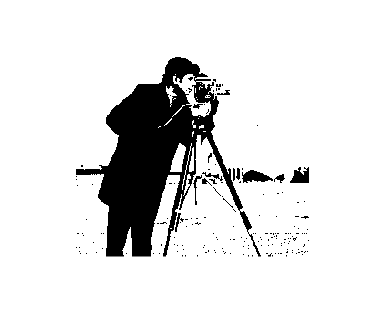

bin_img=imbinarize(img,th_value_auto);
imshow(bin_img);

For color image, you can do either intensity thresholding or color thresholding.

# `Color thresholding `

For color images, you can perform two forms of thresholding can be done.

- Intensity Thresholding - This is exactly Greyscale Thresholding.

- Color Thresholding - In this method, we set boundries to color information, to allow and reject sepcific color image output.

For performing Color thresholding we normally prefer working eith 'Color Thresholder' App in MATLAB.

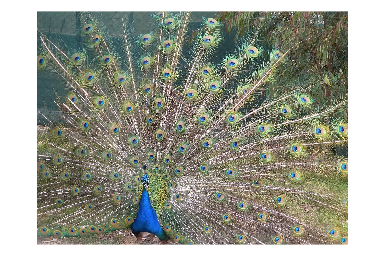

colorThresholder %To launch color thresholder app
                 %Color Thresholder app
img=imread('peacock.jpg');
imshow(img);

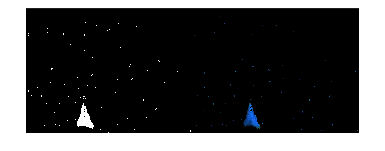

[binmask,colorth_out]=createMask(img);
imshowpair(binmask,colorth_out,'montage');

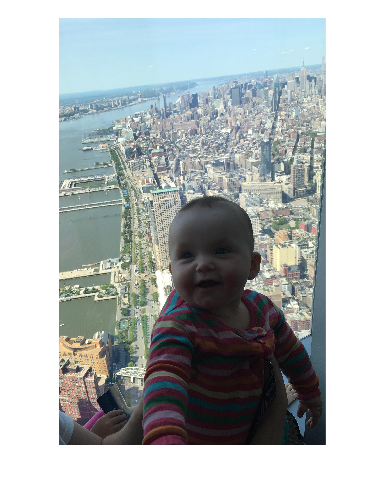

img1=imread('baby.jpg');
imshow(img1);

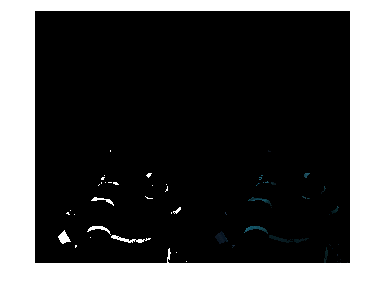

[binmask,colorth_out]=createMask(img1);
imshowpair(binmask,colorth_out,'montage');